% Load ENTSO-E refference csv data from their site
filename = "resources/Date_ENTO-E_Hydropower_2025-2026.csv";
if exist(filename, 'file') == 2
    % Set VariableNamingRule to preserve exact headers from CSV
    opts = detectImportOptions(filename);
    opts.VariableNamingRule = 'preserve';
    entsoe_data = readtable(filename, opts);
    disp('-> ENTSO-E Reference Data loaded successfully.');

    % Filtering the table (using exact column names with parentheses)
    isHydro = contains(entsoe_data.('Production Type'), 'Hydro', 'IgnoreCase', true);
    isTargetYear = ismember(entsoe_data.('Year'), [2025, 2026]); % Actualizat la 2025 și 2026

    % Create a dedicated sub-table for our hydropower project reference
    hydroProjectTable = entsoe_data(isHydro & isTargetYear, {'Year', 'Production Type', 'Installed Capacity (MW)'});

    % Display the filtered table clearly in MATLAB Live Script
    disp('EXTRACTED HYDROPOWER REFERENCE TABLE (RO - 2025/2026):');

    disp(hydroProjectTable);
else 
    warning('ENTSO-E CSV file not found in the "resources" folder.');
end

-> ENTSO-E Reference Data loaded successfully.


EXTRACTED HYDROPOWER REFERENCE TABLE (RO - 2025/2026):


    Year             Production Type              Installed Capacity (MW)
    ____    __________________________________    _______________________

    2025    {'Hydro Pumped Storage'          }          {'n/e'    }      
    2025    {'Hydro Run-of-river and pondage'}          {'2780.00'}      
    2025    {'Hydro Water Reservoir'         }          {'3352.00'}      
    2026    {'Hydro Pumped Storage'          }          {'n/e'    }      
    2026    {'Hydro Run-of-river and pondage'}          {'2780.00'}      
    2026    {'Hydro Water Reservoir'         }          {'3404.00'}      



%% Generate Synthetic Training Data (Physics-Based)
% Simulating operational parameters for a hydropower turbine
rng(42);                  % Set seed for reproducibility
n = 1500;                 % Number of samples

Q = 10 + (220 - 10) * rand(n, 1);  % Water discharge Q [m^3/s] (range 10 between 220)
H = 20 + (65 - 20) * rand(n, 1);   % Hydraulic head H [m] (range 20 between 65)

% Physical constants & formula for active power: P = (eta * rho * g * Q * H) / 1e6
eta = 0.88;   % Turbine efficiency (88%)
rho = 1000;   % Water density [kg/m^3]
g = 9.81;     % Gravitational acceleration [m/s^2]

% Active power P in Megawatts (MW) with slight sensor/operational noise
P = (eta * rho * g * Q .* H) / 1e6 + randn(n, 1) * 0.3;

% Input matrix X (Features) and Target vector Y (Response)
X = [Q, H];
Y = P;

disp('Synthetic training dataset generated successfully based on physical laws.');

Synthetic training dataset generated successfully based on physical laws.


% Train Regression Neural Network (ANN) using fitrnet
disp('Training Regression Neural Network (fitrnet)...');

Training Regression Neural Network (fitrnet)...



% Training a feed-forward neural network for regression with 2 hidden layers ([12, 6])
Mdl = fitrnet(X, Y, 'LayerSizes', [12 6], 'Standardize', true, 'Verbose', 0);

disp('ANN Training Completed Successfully.');

ANN Training Completed Successfully.



% Evaluate Model Performance & Plot Results
YPred = predict(Mdl, X);
MSE = mean((Y - YPred).^2);
fprintf('Trained ANN Model - Mean Squared Error (MSE): %.4f\n', MSE);

Trained ANN Model - Mean Squared Error (MSE): 0.4391


% Display Synthetic Dataset Sample
% Create a table for better visualization in MATLAB Live Script
syntheticTable = table(Q, H, P, 'VariableNames', {'Discharge_Q_m3s', 'HydraulicHead_H_m', 'ActivePower_P_MW'});

disp(head(syntheticTable, 100)); % SYNTHETIC TRAINING DATASET SAMPLE (First 100 rows)

    Discharge_Q_m3s    HydraulicHead_H_m    ActivePower_P_MW
    _______________    _________________    ________________

        88.653              43.359               33.343     
        209.65              41.563               75.344     
        163.72              21.154               29.716     
        135.72              35.356               41.627     
        42.764              37.109               13.799     
        42.759              37.947               14.651     
        22.198              46.108               9.2665     
         191.9              44.012                72.59     
        136.23              47.356                55.79     
         158.7               54.42               74.293     
        14.323              56.584               7.0092     
        213.68              52.316               96.332     
        184.81              62.999         

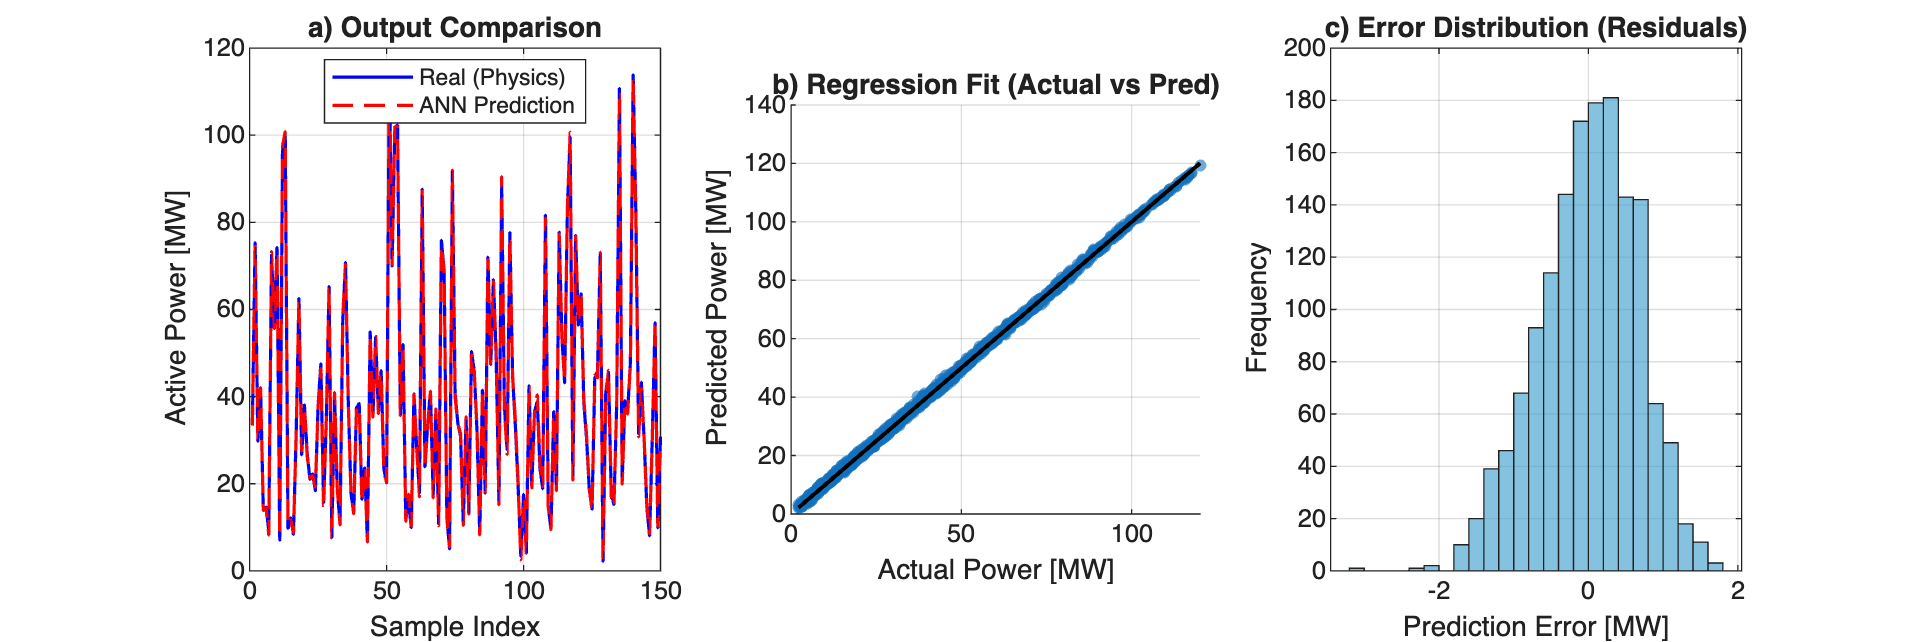

% Advanced Alternative Visualizations for Regression

% Generate predictions for whole set
YPred = predict(Mdl, X);

% Creates a 3 graphs subplot
figure('Name', 'Advanced ANN Performance Analysis', 'Color', 'w', 'Position', [100, 100, 1200, 400]);

% Graph 1: Comparison through sampling (first 150 points) ---
subplot(1, 3, 1);
plot(Y(1:150), 'b-', 'LineWidth', 1.2); hold on;
plot(YPred(1:150), 'r--', 'LineWidth', 1.2);
legend('Real (Physics)', 'ANN Prediction', 'Location', 'Best');
xlabel('Sample Index');
ylabel('Active Power [MW]');
title('a) Output Comparison');
grid on;
% --- Graph 2: Scatter Plot (Actual vs. Predicted)
subplot(1, 3, 2);
scatter(Y, YPred, 20, 'filled', 'MarkerFaceAlpha', 0.6); hold on;

% Perfect Regression Line (y = x)
minVal = min([Y; YPred]);
maxVal = max([Y; YPred]);
plot([minVal, maxVal], [minVal, maxVal], 'k-', 'LineWidth', 1.5);
xlabel('Actual Power [MW]');
ylabel('Predicted Power [MW]');
title('b) Regression Fit (Actual vs Pred)');
grid on;
axis square;

% Graph 3: Errors Graph
subplot(1, 3, 3);
residuals = Y - YPred;
histogram(residuals, 25, 'FaceColor', [0.2, 0.6, 0.8]);
xlabel('Prediction Error [MW]');
ylabel('Frequency');
title('c) Error Distribution (Residuals)');
grid on;

% Display Model Hyperparameters and Architecture
disp('REGRESSION NEURAL NETWORK (fitrnet) HYPERPARAMETERS:');

REGRESSION NEURAL NETWORK (fitrnet) HYPERPARAMETERS:


% Showing model object (shows all parameters)
disp(Mdl);

  RegressionNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 1500
               LayerSizes: [12 6]
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [761×7 table]


  Properties, Methods



% Exporting Models to Simulink 
saveLearnerForCoder(Mdl, 'trained_ann_model.mat');
disp('Trained ANN model saved to trained_ann_model.mat');

Trained ANN model saved to trained_ann_model.mat
